clear all;
close all;

t = (0:0.1:30);
ys = 1*sin(2*pi*0.0333*t);
noiseey = ys + 1 *(-1 + (1+1)*rand(1,301));
noiseey2 = ys + 1 *(-1 + (1+1)*rand(1,301));



x_hat = zeros(301:1);
y_hat = zeros(301:1);


t = 0.1;      %time
xd_ = 0.5;   %velocity
yd_ = 0.5;   %velocity
x_ = noiseey(1);     %initial x state 
y_ = noiseey2(1);     %initial y state 

x = noiseey(1);      %initial x measurment
xd = 0.5;     %initial velocity measurment
y = noiseey2(1);      %initial y measurment
yd = 0.5;     %initial y velocity measurment

w = 0.2;   %process noise 
vx = 1;    %x measurment noise 
vy = 1;    %y measurment noise 

% E = [1; 
%      1;
%      0;
%      0];      %initial location estimate / error covariance

 F = [1 0 t 0;      %state update matrix 
      0 1 0 t;
      0 0 1 0;
      0 0 0 1];
 
 W = [1/2*t^2*w;    %noise/acceleration
     1/2*t^2*w;
     t*w;
     t*w];
 
 H = [1 0 0 0;      %measurment matrix C
      0 1 0 0];

 X_ = [x_;          %initial state matrix
       y_;
       xd_;
       yd_]

X_ =     0.8592
   -0.2064
    0.5000
    0.5000



 Xp = F * X_ + W   %estimate of initial location?? What is being updated (Q_estimate)

Xp =     0.9102
   -0.1554
    0.5200
    0.5200


 
 Q = [t^4*w^2/4 0 t^3*w^2/2 0;      %process covariance matrix
      0 t^4*w^2/4 0 t^3*w^2/2;
      t^3*w^2/2 0 t^w*w^2 0;
      0 t^3*w^2/2 0 t^2*w^2]

Q =     0.0000         0    0.0000         0
         0    0.0000         0    0.0000
    0.0000         0    0.0252         0
         0    0.0000         0    0.0004


 
%  Q = W * W'    
 
 
 Xm = [x;
       y;
       xd;
       yd;]         %measurment

Xm =     0.8592
   -0.2064
    0.5000
    0.5000


  
 V = [vx; 
     vy];           %error in measurment
 
R = [vx^2 0;        %measurment covariance matrix
     0 vy^2]

R =      1     0
     0     1


     
%  R = V * V.'   
 
 Z = H * Xm + V     %measurment update equation??

Z =     1.8592
    0.7936


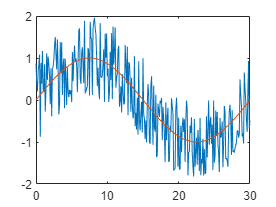

 
t = (0:0.1:30);

plot(t,noiseey)
hold on
plot(t,ys)

E = Q;                              %initial positon variance
%loop
 for i = 1:301
     
    Xm(1) = noiseey(i);             %get measurments
    Xm(2) = noiseey2(i);

    
    
    E = F * E * F' + Q;             %Predict next covariance
    
    K = E*H'*inv(H*E*H'+R)          %Kalman Gain
    
    Xp = Xp + K *(Xm(1:2,:) - H*Xp) %update state estimate
    
    x_hat(i) = Xp(1);               %get x 
    y_hat(i) = Xp(2);               %get y
    
    E = (eye(4) - K*H)*E;           %update covariance estimate
    
    
    Xp = F * Xp + W*0.0005          %Predict next state with laste state and predicted motion
 end

Xm =     0.8592
   -0.2064
    0.5000
    0.5000


K =     0.0003         0
         0    0.0000
    0.0026         0
         0    0.0001


Xp =     0.9102
   -0.1554
    0.5199
    0.5200


Xp =     0.9622
   -0.1034
    0.5199
    0.5200


Xm =     0.4143
   -0.8311
    0.5000
    0.5000


K =     0.0013         0
         0    0.0000
    0.0076         0
         0    0.0002


Xp =     0.9615
   -0.1034
    0.5157
    0.5199


Xp =     1.0131
   -0.0514
    0.5157
    0.5199


Xm =     0.2074
    0.4100
    0.5000
    0.5000


K =     0.0035         0
         0    0.0001
    0.0152         0
         0    0.0003


Xp =     1.0102
   -0.0514
    0.5035
    0.5200


Xp =     1.0606
    0.0006
    0.5035
    0.5200


Xm =     0.6935
   -0.1325
    0.5000
    0.5000


K =     0.0075         0
         0    0.0002
    0.0250         0
         0    0.0005


Xp =     1.0578
    0.0006
    0.4943
    0.5200


Xp =     1.1072
    0.0526
    0.4943
    0.5200


Xm =     0.8416
    1.0493
    0.5000
    0.5000


K =     0.0136         0
         0    0.0003
    0.0371         0
         0    0.0007


Xp =     1.1036
    0.0529
    0.4845
    0.5207


Xp =     1.1521
    0.1049
    0.4845
    0.5207


Xm =     1.0822
   -0.0912
    0.5000
    0.5000


K =     0.0220         0
         0    0.0005
    0.0509         0
         0    0.0010


Xp =     1.1505
    0.1048
    0.4809
    0.5205


Xp =     1.1986
    0.1569
    0.4810
    0.5205


Xm =    -0.8737
    0.3666
    0.5000
    0.5000


K =     0.0328         0
         0    0.0007
    0.0658         0
         0    0.0013


Xp =     1.1307
    0.1570
    0.3445
    0.5208


Xp =     1.1651
    0.2091
    0.3445
    0.5208


Xm =     0.8768
   -0.5453
    0.5000
    0.5000


K =     0.0457         0
         0    0.0010
    0.0812         0
         0    0.0016


Xp =     1.1519
    0.2084
    0.3211
    0.5196


Xp =     1.1841
    0.2604
    0.3211
    0.5196


Xm =     0.3917
   -0.0707
    0.5000
    0.5000


K =     0.0602         0
         0    0.0013
    0.0961         0
         0    0.0020


Xp =     1.1364
    0.2599
    0.2450
    0.5189


Xp =     1.1609
    0.3118
    0.2450
    0.5190


Xm =     1.1671
   -0.4905
    0.5000
    0.5000


K =     0.0755         0
         0    0.0018
    0.1098         0
         0    0.0024


Xp =     1.1613
    0.3104
    0.2457
    0.5170


Xp =     1.1859
    0.3621
    0.2457
    0.5170


Xm =     0.2631
    0.7239
    0.5000
    0.5000


K =     0.0908         0
         0    0.0023
    0.1215         0
         0    0.0029


Xp =     1.1021
    0.3629
    0.1335
    0.5181


Xp =     1.1155
    0.4147
    0.1335
    0.5181


Xm = 4×1
    0.1872
    0.9703
    0.5000
    0.5000


K = 4×2
    0.1052         0
         0    0.0029
    0.1309         0
         0    0.0033


Xp = 4×1
    1.0178
    0.4163
    0.0120
    0.5199


Xp = 4×1
    1.0190
    0.4683
    0.0120
    0.5199


Xm = 4×1
    0.8511
   -0.0500
    0.5000
    0.5000


K = 4×2
    0.1181         0
         0    0.0036
    0.1378         0
         0    0.0039


Xp = 4×1
    0.9992
    0.4665
   -0.0111
    0.5179


Xp = 4×1
    0.9981
    0.5183
   -0.0111
    0.5179


Xm = 4×1
   -0.2757
    0.6397
    0.5000
    0.5000


K = 4×2
    0.1291         0
         0    0.0044
    0.1424         0
         0    0.0044


Xp = 4×1
    0.8336
    0.5188
   -0.1925
    0.5185


Xp = 4×1
    0.8144
    0.5706
   -0.1925
    0.5185


Xm = 4×1
    0.2849
   -0.1230
    0.5000
    0.5000


K = 4×2
    0.1381         0
         0    0.0053
    0.1451         0
         0    0.0050


Xp = 4×1
    0.7413
    0.5669
   -0.2693
    0.5150


Xp = 4×1
    0.7143
    0.6184
   -0.2693
    0.5150


Xm = 4×1
    1.1104
    0.3700
    0.5000
    0.5000


K = 4×2
    0.1451         0
         0    0.0064
    0.1463         0
         0    0.0056


Xp = 4×1
    0.7718
    0.6169
   -0.2114
    0.5136


Xp = 4×1
    0.7507
    0.6682
   -0.2114
    0.5136


Xm = 4×1
    0.4779
    0.9934
    0.5000
    0.5000


K = 4×2
    0.1503         0
         0    0.0075
    0.1464         0
         0    0.0063


Xp = 4×1
    0.7097
    0.6707
   -0.2513
    0.5157


Xp = 4×1
    0.6845
    0.7222
   -0.2513
    0.5157


Xm = 4×1
    1.0386
    0.5432
    0.5000
    0.5000


K = 4×2
    0.1541         0
         0    0.0087
    0.1459         0
         0    0.0069


Xp = 4×1
    0.7391
    0.7207
   -0.1997
    0.5144


Xp = 4×1
    0.7191
    0.7721
   -0.1997
    0.5145


Xm = 4×1
    0.8451
    0.0384
    0.5000
    0.5000


K = 4×2
    0.1568         0
         0    0.0101
    0.1450         0
         0    0.0076


Xp = 4×1
    0.7389
    0.7647
   -0.1814
    0.5089


Xp = 4×1
    0.7207
    0.8156
   -0.1814
    0.5089


Xm = 4×1
    0.5591
   -0.0144
    0.5000
    0.5000


K = 4×2
    0.1585         0
         0    0.0116
    0.1439         0
         0    0.0083


Xp = 4×1
    0.6951
    0.8060
   -0.2046
    0.5020


Xp = 4×1
    0.6747
    0.8562
   -0.2046
    0.5020


Xm = 4×1
   -0.1002
    0.3115
    0.5000
    0.5000


K = 4×2
    0.1596         0
         0    0.0131
    0.1429         0
         0    0.0090


Xp = 4×1
    0.5510
    0.8490
   -0.3154
    0.4971


Xp = 4×1
    0.5195
    0.8988
   -0.3154
    0.4971


Xm = 4×1
    0.7582
    0.2707
    0.5000
    0.5000


K = 4×2
    0.1602         0
         0    0.0148
    0.1420         0
         0    0.0097


Xp = 4×1
    0.5577
    0.8895
   -0.2815
    0.4910


Xp = 4×1
    0.5296
    0.9386
   -0.2814
    0.4910


Xm = 4×1
   -0.3888
    0.1634
    0.5000
    0.5000


K = 4×2
    0.1606         0
         0    0.0165
    0.1414         0
         0    0.0104


Xp = 4×1
    0.3821
    0.9257
   -0.4113
    0.4829


Xp = 4×1
    0.3410
    0.9740
   -0.4112
    0.4829


Xm = 4×1
    0.7148
    0.5795
    0.5000
    0.5000


K = 4×2
    0.1607         0
         0    0.0184
    0.1409         0
         0    0.0111


Xp = 4×1
    0.4011
    0.9668
   -0.3586
    0.4785


Xp = 4×1
    0.3652
    1.0146
   -0.3586
    0.4785


Xm = 4×1
    0.8032
    0.9664
    0.5000
    0.5000


K = 4×2
    0.1608         0
         0    0.0203
    0.1406         0
         0    0.0118


Xp = 4×1
    0.4356
    1.0137
   -0.2970
    0.4780


Xp = 4×1
    0.4059
    1.0615
   -0.2970
    0.4780


Xm = 4×1
    0.9591
    0.3482
    0.5000
    0.5000


K = 4×2
    0.1608         0
         0    0.0222
    0.1405         0
         0    0.0125


Xp = 4×1
    0.4948
    1.0456
   -0.2193
    0.4691


Xp = 4×1
    0.4729
    1.0925
   -0.2193
    0.4691


Xm = 4×1
    1.2991
    0.3763
    0.5000
    0.5000


K = 4×2
    0.1608         0
         0    0.0242
    0.1406         0
         0    0.0132


Xp = 4×1
    0.6057
    1.0751
   -0.1031
    0.4596


Xp = 4×1
    0.5954
    1.1211
   -0.1031
    0.4596


Xm = 4×1
    1.5000
   -0.2149
    0.5000
    0.5000


K = 4×2
    0.1608         0
         0    0.0263
    0.1408         0
         0    0.0138


Xp = 4×1
    0.7408
    1.0860
    0.0242
    0.4411


Xp = 4×1
    0.7433
    1.1301
    0.0242
    0.4411


Xm = 4×1
    1.0910
   -0.3982
    0.5000
    0.5000


K = 4×2
    0.1608         0
         0    0.0283
    0.1410         0
         0    0.0144


Xp = 4×1
    0.7992
    1.0868
    0.0732
    0.4191


Xp = 4×1
    0.8065
    1.1287
    0.0733
    0.4191


Xm = 4×1
    0.7331
    0.1506
    0.5000
    0.5000


K = 4×2
    0.1609         0
         0    0.0304
    0.1414         0
         0    0.0150


Xp = 4×1
    0.7947
    1.0990
    0.0629
    0.4044


Xp = 4×1
    0.8010
    1.1395
    0.0629
    0.4044


Xm = 4×1
    1.4439
    0.2223
    0.5000
    0.5000


K = 4×2
    0.1611         0
         0    0.0324
    0.1418         0
         0    0.0156


Xp = 4×1
    0.9045
    1.1098
    0.1541
    0.3901


Xp = 4×1
    0.9199
    1.1488
    0.1541
    0.3901


Xm = 4×1
    0.7643
    0.9115
    0.5000
    0.5000


K = 4×2
    0.1612         0
         0    0.0344
    0.1422         0
         0    0.0161


Xp = 4×1
    0.8948
    1.1406
    0.1319
    0.3863


Xp = 4×1
    0.9080
    1.1792
    0.1319
    0.3863


Xm = 4×1
   -0.3454
    1.5345
    0.5000
    0.5000


K = 4×2
    0.1614         0
         0    0.0363
    0.1426         0
         0    0.0166


Xp = 4×1
    0.7058
    1.1922
   -0.0468
    0.3922


Xp = 4×1
    0.7011
    1.2314
   -0.0468
    0.3922


Xm = 4×1
   -0.1214
    1.5084
    0.5000
    0.5000


K = 4×2
    0.1616         0
         0    0.0383
    0.1430         0
         0    0.0170


Xp = 4×1
    0.5682
    1.2420
   -0.1645
    0.3969


Xp = 4×1
    0.5517
    1.2817
   -0.1644
    0.3969


Xm = 4×1
    1.3783
    0.5687
    0.5000
    0.5000


K = 4×2
    0.1618         0
         0    0.0401
    0.1434         0
         0    0.0174


Xp = 4×1
    0.6854
    1.2531
   -0.0459
    0.3845


Xp = 4×1
    0.6809
    1.2915
   -0.0459
    0.3845


Xm = 4×1
    0.6372
    0.1495
    0.5000
    0.5000


K = 4×2
    0.1619         0
         0    0.0419
    0.1437         0
         0    0.0178


Xp = 4×1
    0.6738
    1.2437
   -0.0522
    0.3642


Xp = 4×1
    0.6686
    1.2802
   -0.0522
    0.3642


Xm = 4×1
    1.3737
    1.2118
    0.5000
    0.5000


K = 4×2
    0.1621         0
         0    0.0435
    0.1440         0
         0    0.0181


Xp = 4×1
    0.7829
    1.2772
    0.0494
    0.3630


Xp = 4×1
    0.7878
    1.3135
    0.0494
    0.3630


Xm = 4×1
    0.1179
    1.2178
    0.5000
    0.5000


K = 4×2
    0.1623         0
         0    0.0451
    0.1443         0
         0    0.0183


Xp = 4×1
    0.6791
    1.3092
   -0.0473
    0.3613


Xp = 4×1
    0.6744
    1.3453
   -0.0473
    0.3613


Xm = 4×1
    0.8185
    1.1952
    0.5000
    0.5000


K = 4×2
    0.1625         0
         0    0.0466
    0.1445         0
         0    0.0186


Xp = 4×1
    0.6978
    1.3383
   -0.0264
    0.3585


Xp = 4×1
    0.6951
    1.3741
   -0.0264
    0.3585


Xm = 4×1
    0.9882
    1.2158
    0.5000
    0.5000


K = 4×2
    0.1626         0
         0    0.0480
    0.1447         0
         0    0.0188


Xp = 4×1
    0.7428
    1.3665
    0.0160
    0.3555


Xp = 4×1
    0.7444
    1.4021
    0.0160
    0.3555


Xm = 4×1
   -0.1934
   -0.0456
    0.5000
    0.5000


K = 4×2
    0.1628         0
         0    0.0493
    0.1448         0
         0    0.0190


Xp = 4×1
    0.5918
    1.3306
   -0.1199
    0.3281


Xp = 4×1
    0.5798
    1.3635
   -0.1199
    0.3281


Xm = 4×1
    0.9859
    1.1196
    0.5000
    0.5000


K = 4×2
    0.1629         0
         0    0.0506
    0.1450         0
         0    0.0191


Xp = 4×1
    0.6459
    1.3511
   -0.0610
    0.3234


Xp = 4×1
    0.6398
    1.3835
   -0.0610
    0.3235


Xm = 4×1
    0.4948
    0.6965
    0.5000
    0.5000


K = 4×2
    0.1630         0
         0    0.0517
    0.1451         0
         0    0.0192


Xp = 4×1
    0.6162
    1.3480
   -0.0820
    0.3103


Xp = 4×1
    0.6080
    1.3790
   -0.0820
    0.3103


Xm = 4×1
   -0.1178
    0.2075
    0.5000
    0.5000


K = 4×2
    0.1631         0
         0    0.0527
    0.1451         0
         0    0.0193


Xp = 4×1
    0.4896
    1.3173
   -0.1873
    0.2877


Xp = 4×1
    0.4709
    1.3460
   -0.1873
    0.2877


Xm = 4×1
    0.7751
   -0.0070
    0.5000
    0.5000


K = 4×2
    0.1631         0
         0    0.0536
    0.1452         0
         0    0.0194


Xp = 4×1
    0.5205
    1.2735
   -0.1432
    0.2615


Xp = 4×1
    0.5062
    1.2996
   -0.1432
    0.2615


Xm = 4×1
    0.1935
    1.4556
    0.5000
    0.5000


K = 4×2
    0.1632         0
         0    0.0545
    0.1452         0
         0    0.0194


Xp = 4×1
    0.4552
    1.3081
   -0.1886
    0.2645


Xp = 4×1
    0.4363
    1.3346
   -0.1886
    0.2645


Xm = 4×1
    0.0668
    0.1706
    0.5000
    0.5000


K = 4×2
    0.1632         0
         0    0.0552
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3760
    1.2703
   -0.2422
    0.2419


Xp = 4×1
    0.3518
    1.2944
   -0.2422
    0.2419


Xm = 4×1
    0.2434
    0.1595
    0.5000
    0.5000


K = 4×2
    0.1633         0
         0    0.0559
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3341
    1.2310
   -0.2580
    0.2199


Xp = 4×1
    0.3083
    1.2530
   -0.2580
    0.2199


Xm = 4×1
    0.1368
    1.1758
    0.5000
    0.5000


K = 4×2
    0.1633         0
         0    0.0565
    0.1453         0
         0    0.0194


Xp = 4×1
    0.2803
    1.2486
   -0.2829
    0.2184


Xp = 4×1
    0.2520
    1.2704
   -0.2829
    0.2184


Xm = 4×1
    0.2330
    1.6436
    0.5000
    0.5000


K = 4×2
    0.1633         0
         0    0.0571
    0.1453         0
         0    0.0194


Xp = 4×1
    0.2489
    1.2917
   -0.2856
    0.2257


Xp = 4×1
    0.2203
    1.3143
   -0.2856
    0.2257


Xm = 4×1
   -0.0492
    0.8986
    0.5000
    0.5000


K = 4×2
    0.1633         0
         0    0.0576
    0.1453         0
         0    0.0194


Xp = 4×1
    0.1763
    1.2904
   -0.3248
    0.2176


Xp = 4×1
    0.1438
    1.3121
   -0.3248
    0.2176


Xm = 4×1
    1.1462
    1.2812
    0.5000
    0.5000


K = 4×2
    0.1633         0
         0    0.0580
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3075
    1.3103
   -0.1791
    0.2170


Xp = 4×1
    0.2896
    1.3320
   -0.1791
    0.2170


Xm = 4×1
    0.4494
    0.1929
    0.5000
    0.5000


K = 4×2
    0.1633         0
         0    0.0584
    0.1453         0
         0    0.0193


Xp = 4×1
    0.3157
    1.2656
   -0.1559
    0.1950


Xp = 4×1
    0.3001
    1.2851
   -0.1559
    0.1950


Xm = 4×1
    0.9724
    1.8021
    0.5000
    0.5000


K = 4×2
    0.1633         0
         0    0.0587
    0.1453         0
         0    0.0193


Xp = 4×1
    0.4100
    1.3154
   -0.0582
    0.2050


Xp = 4×1
    0.4041
    1.3359
   -0.0582
    0.2050


Xm = 4×1
    1.2947
    0.9861
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0590
    0.1453         0
         0    0.0192


Xp = 4×1
    0.5496
    1.3153
    0.0712
    0.1983


Xp = 4×1
    0.5567
    1.3351
    0.0712
    0.1983


Xm = 4×1
    0.9113
    1.2725
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0592
    0.1453         0
         0    0.0192


Xp = 4×1
    0.6147
    1.3314
    0.1227
    0.1971


Xp = 4×1
    0.6269
    1.3511
    0.1227
    0.1971


Xm = 4×1
    0.9930
   -0.0055
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0594
    0.1453         0
         0    0.0191


Xp = 4×1
    0.6867
    1.2705
    0.1759
    0.1711


Xp = 4×1
    0.7043
    1.2877
    0.1759
    0.1711


Xm = 4×1
    0.8197
    1.5477
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0596
    0.1453         0
         0    0.0191


Xp = 4×1
    0.7232
    1.3031
    0.1927
    0.1761


Xp = 4×1
    0.7424
    1.3208
    0.1927
    0.1761


Xm = 4×1
    0.1847
    1.4341
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0597
    0.1453         0
         0    0.0191


Xp = 4×1
    0.6513
    1.3275
    0.1117
    0.1783


Xp = 4×1
    0.6625
    1.3454
    0.1117
    0.1783


Xm = 4×1
    0.9247
    0.1843
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0598
    0.1453         0
         0    0.0190


Xp = 4×1
    0.7053
    1.2759
    0.1498
    0.1562


Xp = 4×1
    0.7203
    1.2915
    0.1498
    0.1562


Xm = 4×1
    1.6567
    1.0008
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0599
    0.1453         0
         0    0.0190


Xp = 4×1
    0.8733
    1.2741
    0.2859
    0.1507


Xp = 4×1
    0.9019
    1.2892
    0.2859
    0.1507


Xm = 4×1
    1.7048
    0.6086
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0600
    0.1453         0
         0    0.0189


Xp = 4×1
    1.0330
    1.2483
    0.4025
    0.1378


Xp = 4×1
    1.0733
    1.2621
    0.4025
    0.1378


Xm = 4×1
    0.5034
    1.0557
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0601
    0.1453         0
         0    0.0189


Xp = 4×1
    0.9802
    1.2497
    0.3197
    0.1339


Xp = 4×1
    1.0122
    1.2631
    0.3197
    0.1340


Xm = 4×1
    0.3852
    0.7660
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0601
    0.1453         0
         0    0.0189


Xp = 4×1
    0.9097
    1.2332
    0.2286
    0.1246


Xp = 4×1
    0.9326
    1.2457
    0.2287
    0.1246


Xm = 4×1
    1.1032
    0.8035
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0188


Xp = 4×1
    0.9605
    1.2191
    0.2534
    0.1163


Xp = 4×1
    0.9858
    1.2307
    0.2535
    0.1163


Xm = 4×1
    1.2585
    0.3393
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0188


Xp = 4×1
    1.0304
    1.1771
    0.2931
    0.0995


Xp = 4×1
    1.0597
    1.1870
    0.2931
    0.0995


Xm = 4×1
    0.8161
    0.4928
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0188


Xp = 4×1
    1.0199
    1.1452
    0.2577
    0.0865


Xp = 4×1
    1.0457
    1.1539
    0.2577
    0.0865


Xm = 4×1
    0.3977
    0.0268
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0188


Xp = 4×1
    0.9398
    1.0860
    0.1636
    0.0653


Xp = 4×1
    0.9562
    1.0925
    0.1636
    0.0654


Xm = 4×1
    1.8849
    1.8364
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    1.1079
    1.1373
    0.2985
    0.0793


Xp = 4×1
    1.1377
    1.1453
    0.2985
    0.0793


Xm = 4×1
    0.1561
    1.2993
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    0.9774
    1.1545
    0.1559
    0.0822


Xp = 4×1
    0.9930
    1.1628
    0.1559
    0.0822


Xm = 4×1
    0.2058
    1.8596
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    0.8644
    1.2047
    0.0415
    0.0953


Xp = 4×1
    0.8685
    1.2143
    0.0415
    0.0953


Xm = 4×1
    0.2804
    0.3234
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    0.7725
    1.1606
   -0.0439
    0.0786


Xp = 4×1
    0.7681
    1.1685
   -0.0439
    0.0786


Xm = 4×1
    0.3309
    1.8401
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    0.6966
    1.2089
   -0.1074
    0.0912


Xp = 4×1
    0.6859
    1.2180
   -0.1074
    0.0912


Xm = 4×1
    1.2410
    1.5884
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    0.7766
    1.2403
   -0.0268
    0.0981


Xp = 4×1
    0.7739
    1.2502
   -0.0268
    0.0981


Xm = 4×1
    1.1472
    1.1545
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    0.8349
    1.2444
    0.0275
    0.0963


Xp = 4×1
    0.8376
    1.2540
    0.0275
    0.0963


Xm = 4×1
    0.1042
    0.8801
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    0.7178
    1.2315
   -0.0791
    0.0893


Xp = 4×1
    0.7099
    1.2404
   -0.0791
    0.0893


Xm = 4×1
    1.8622
    0.5150
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0602
    0.1453         0
         0    0.0187


Xp = 4×1
    0.8981
    1.1967
    0.0884
    0.0758


Xp = 4×1
    0.9070
    1.2043
    0.0884
    0.0758


Xm = 4×1
    1.4565
    1.5031
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0187


Xp = 4×1
    0.9967
    1.2223
    0.1682
    0.0814


Xp = 4×1
    1.0136
    1.2304
    0.1682
    0.0814


Xm = 4×1
    1.4738
    0.4555
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0187


Xp = 4×1
    1.0888
    1.1838
    0.2351
    0.0669


Xp = 4×1
    1.1123
    1.1904
    0.2351
    0.0669


Xm = 4×1
    0.1234
    0.1250
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0188


Xp = 4×1
    0.9507
    1.1262
    0.0914
    0.0469


Xp = 4×1
    0.9599
    1.1309
    0.0914
    0.0469


Xm = 4×1
    1.7156
    1.5294
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0188


Xp = 4×1
    1.0833
    1.1549
    0.2013
    0.0544


Xp = 4×1
    1.1035
    1.1604
    0.2013
    0.0544


Xm = 4×1
    1.8611
    1.3347
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0188


Xp = 4×1
    1.2272
    1.1709
    0.3114
    0.0577


Xp = 4×1
    1.2584
    1.1766
    0.3114
    0.0577


Xm = 4×1
    1.9583
    1.4199
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0188


Xp = 4×1
    1.3727
    1.1913
    0.4131
    0.0622


Xp = 4×1
    1.4140
    1.1975
    0.4131
    0.0622


Xm = 4×1
    1.7042
    1.2704
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0188


Xp = 4×1
    1.4614
    1.2019
    0.4553
    0.0636


Xp = 4×1
    1.5069
    1.2083
    0.4553
    0.0636


Xm = 4×1
    1.5537
    0.8207
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0188


Xp = 4×1
    1.5146
    1.1849
    0.4621
    0.0563


Xp = 4×1
    1.5608
    1.1906
    0.4621
    0.0563


Xm = 4×1
    1.0053
    0.7600
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0189


Xp = 4×1
    1.4700
    1.1646
    0.3813
    0.0482


Xp = 4×1
    1.5082
    1.1694
    0.3814
    0.0482


Xm = 4×1
    0.3292
    1.6063
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0603
    0.1453         0
         0    0.0189


Xp = 4×1
    1.3156
    1.1958
    0.2100
    0.0565


Xp = 4×1
    1.3366
    1.2014
    0.2100
    0.0565


Xm = 4×1
    0.7662
    0.6039
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0604
    0.1453         0
         0    0.0189


Xp = 4×1
    1.2434
    1.1653
    0.1272
    0.0452


Xp = 4×1
    1.2561
    1.1699
    0.1272
    0.0452


Xm = 4×1
    0.2315
    1.5927
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0604
    0.1453         0
         0    0.0189


Xp = 4×1
    1.0887
    1.1954
   -0.0217
    0.0532


Xp = 4×1
    1.0866
    1.2007
   -0.0217
    0.0532


Xm = 4×1
    0.0196
    1.5360
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0604
    0.1453         0
         0    0.0189


Xp = 4×1
    0.9123
    1.2210
   -0.1767
    0.0596


Xp = 4×1
    0.8946
    1.2269
   -0.1767
    0.0596


Xm = 4×1
    1.8299
    1.6562
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0604
    0.1453         0
         0    0.0190


Xp = 4×1
    1.0474
    1.2529
   -0.0408
    0.0677


Xp = 4×1
    1.0433
    1.2596
   -0.0408
    0.0677


Xm = 4×1
    0.5476
    0.9563
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0605
    0.1453         0
         0    0.0190


Xp = 4×1
    0.9623
    1.2413
   -0.1128
    0.0620


Xp = 4×1
    0.9511
    1.2475
   -0.1128
    0.0620


Xm = 4×1
    0.5290
    1.2093
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0605
    0.1453         0
         0    0.0190


Xp = 4×1
    0.8821
    1.2452
   -0.1741
    0.0612


Xp = 4×1
    0.8647
    1.2513
   -0.1741
    0.0613


Xm = 4×1
    0.5964
    1.8323
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0605
    0.1453         0
         0    0.0190


Xp = 4×1
    0.8209
    1.2865
   -0.2131
    0.0723


Xp = 4×1
    0.7995
    1.2937
   -0.2131
    0.0723


Xm = 4×1
    0.8568
    0.8106
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0605
    0.1453         0
         0    0.0190


Xp = 4×1
    0.8089
    1.2644
   -0.2048
    0.0631


Xp = 4×1
    0.7884
    1.2708
   -0.2048
    0.0631


Xm = 4×1
    1.2107
    0.0344
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0606
    0.1453         0
         0    0.0191


Xp = 4×1
    0.8574
    1.1959
   -0.1434
    0.0396


Xp = 4×1
    0.8431
    1.1998
   -0.1434
    0.0396


Xm = 4×1
   -0.0439
    1.6392
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0606
    0.1453         0
         0    0.0191


Xp = 4×1
    0.6982
    1.2265
   -0.2723
    0.0480


Xp = 4×1
    0.6709
    1.2313
   -0.2723
    0.0480


Xm = 4×1
    1.5810
    1.1590
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0606
    0.1453         0
         0    0.0191


Xp = 4×1
    0.8196
    1.2269
   -0.1400
    0.0466


Xp = 4×1
    0.8056
    1.2315
   -0.1400
    0.0466


Xm = 4×1
    1.0052
    0.5973
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0606
    0.1453         0
         0    0.0191


Xp = 4×1
    0.8382
    1.1931
   -0.1110
    0.0345


Xp = 4×1
    0.8271
    1.1965
   -0.1110
    0.0345


Xm = 4×1
    1.5855
    1.8713
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0607
    0.1453         0
         0    0.0191


Xp = 4×1
    0.9510
    1.2375
   -0.0008
    0.0474


Xp = 4×1
    0.9509
    1.2422
   -0.0008
    0.0474


Xm = 4×1
    0.5628
    0.3154
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0607
    0.1453         0
         0    0.0191


Xp = 4×1
    0.8875
    1.1859
   -0.0572
    0.0297


Xp = 4×1
    0.8818
    1.1889
   -0.0572
    0.0297


Xm = 4×1
    0.7485
    1.1614
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0607
    0.1453         0
         0    0.0192


Xp = 4×1
    0.8600
    1.1872
   -0.0766
    0.0291


Xp = 4×1
    0.8524
    1.1902
   -0.0766
    0.0292


Xm = 4×1
   -0.0461
    1.0555
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0608
    0.1453         0
         0    0.0192


Xp = 4×1
    0.7056
    1.1820
   -0.2071
    0.0266


Xp = 4×1
    0.6849
    1.1846
   -0.2071
    0.0266


Xm = 4×1
    0.1883
    0.6086
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0608
    0.1453         0
         0    0.0192


Xp = 4×1
    0.6038
    1.1496
   -0.2792
    0.0155


Xp = 4×1
    0.5759
    1.1512
   -0.2792
    0.0155


Xm = 4×1
    1.1480
    0.1068
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0608
    0.1453         0
         0    0.0192


Xp = 4×1
    0.6693
    1.0877
   -0.1961
   -0.0045


Xp = 4×1
    0.6497
    1.0872
   -0.1961
   -0.0045


Xm = 4×1
    0.4720
   -0.1394
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0608
    0.1453         0
         0    0.0192


Xp = 4×1
    0.6207
    1.0126
   -0.2219
   -0.0281


Xp = 4×1
    0.5985
    1.0098
   -0.2219
   -0.0281


Xm = 4×1
    1.5948
    0.6401
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0609
    0.1453         0
         0    0.0192


Xp = 4×1
    0.7613
    0.9873
   -0.0771
   -0.0352


Xp = 4×1
    0.7535
    0.9838
   -0.0771
   -0.0352


Xm = 4×1
    0.0214
    0.1533
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0609
    0.1453         0
         0    0.0192


Xp = 4×1
    0.6339
    0.9332
   -0.1835
   -0.0511


Xp = 4×1
    0.6156
    0.9281
   -0.1835
   -0.0511


Xm = 4×1
    1.7488
    1.2235
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0609
    0.1453         0
         0    0.0193


Xp = 4×1
    0.8007
    0.9461
   -0.0188
   -0.0454


Xp = 4×1
    0.7988
    0.9416
   -0.0188
   -0.0454


Xm = 4×1
    0.8384
    0.4992
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0609
    0.1453         0
         0    0.0193


Xp = 4×1
    0.8053
    0.9146
   -0.0131
   -0.0540


Xp = 4×1
    0.8040
    0.9092
   -0.0130
   -0.0539


Xm = 4×1
    1.1585
    1.4278
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0609
    0.1453         0
         0    0.0193


Xp = 4×1
    0.8619
    0.9408
    0.0385
   -0.0440


Xp = 4×1
    0.8658
    0.9364
    0.0385
   -0.0439


Xm = 4×1
    1.7295
    1.1990
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0610
    0.1453         0
         0    0.0193


Xp = 4×1
    1.0069
    0.9524
    0.1640
   -0.0389


Xp = 4×1
    1.0233
    0.9485
    0.1640
   -0.0389


Xm = 4×1
    0.2918
    0.8582
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0610
    0.1453         0
         0    0.0193


Xp = 4×1
    0.9038
    0.9430
    0.0577
   -0.0406


Xp = 4×1
    0.9095
    0.9390
    0.0577
   -0.0406


Xm = 4×1
    0.5304
    0.0551
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0610
    0.1453         0
         0    0.0193


Xp = 4×1
    0.8476
    0.8850
    0.0026
   -0.0577


Xp = 4×1
    0.8479
    0.8793
    0.0026
   -0.0576


Xm = 4×1
    0.6160
    1.6011
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0610
    0.1453         0
         0    0.0193


Xp = 4×1
    0.8100
    0.9233
   -0.0311
   -0.0437


Xp = 4×1
    0.8069
    0.9190
   -0.0310
   -0.0437


Xm = 4×1
    1.1988
    0.2016
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0610
    0.1453         0
         0    0.0193


Xp = 4×1
    0.8709
    0.8752
    0.0259
   -0.0576


Xp = 4×1
    0.8735
    0.8694
    0.0259
   -0.0575


Xm = 4×1
    1.2917
    1.5044
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0611
    0.1453         0
         0    0.0193


Xp = 4×1
    0.9418
    0.9082
    0.0867
   -0.0453


Xp = 4×1
    0.9505
    0.9037
    0.0867
   -0.0453


Xm = 4×1
   -0.1602
    0.0869
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0611
    0.1453         0
         0    0.0193


Xp = 4×1
    0.7690
    0.8538
   -0.0747
   -0.0611


Xp = 4×1
    0.7616
    0.8477
   -0.0747
   -0.0610


Xm = 4×1
   -0.0207
    0.3702
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0611
    0.1453         0
         0    0.0193


Xp = 4×1
    0.6338
    0.8185
   -0.1884
   -0.0703


Xp = 4×1
    0.6149
    0.8115
   -0.1884
   -0.0703


Xm = 4×1
    0.3259
   -0.2184
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0611
    0.1453         0
         0    0.0193


Xp = 4×1
    0.5677
    0.7485
   -0.2304
   -0.0902


Xp = 4×1
    0.5447
    0.7395
   -0.2304
   -0.0902


Xm = 4×1
   -0.2968
    0.8700
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0611
    0.1453         0
         0    0.0193


Xp = 4×1
    0.4072
    0.7475
   -0.3526
   -0.0876


Xp = 4×1
    0.3719
    0.7387
   -0.3526
   -0.0876


Xm = 4×1
    0.6166
   -0.0660
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0611
    0.1453         0
         0    0.0193


Xp = 4×1
    0.4119
    0.6895
   -0.3171
   -0.1032


Xp = 4×1
    0.3802
    0.6792
   -0.3171
   -0.1032


Xm = 4×1
    0.2272
   -0.3544
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0611
    0.1453         0
         0    0.0193


Xp = 4×1
    0.3552
    0.6160
   -0.3393
   -0.1232


Xp = 4×1
    0.3213
    0.6037
   -0.3393
   -0.1232


Xm = 4×1
   -0.1107
    0.9843
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.2507
    0.6270
   -0.4020
   -0.1158


Xp = 4×1
    0.2105
    0.6154
   -0.4020
   -0.1158


Xm = 4×1
   -0.0619
    0.2151
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.1660
    0.5909
   -0.4416
   -0.1235


Xp = 4×1
    0.1219
    0.5786
   -0.4416
   -0.1235


Xm = 4×1
    1.3126
    0.8235
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3164
    0.5935
   -0.2686
   -0.1188


Xp = 4×1
    0.2895
    0.5817
   -0.2686
   -0.1188


Xm = 4×1
    0.8348
    0.2518
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3786
    0.5615
   -0.1893
   -0.1252


Xp = 4×1
    0.3597
    0.5490
   -0.1893
   -0.1252


Xm = 4×1
    0.4026
    0.7203
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3667
    0.5595
   -0.1831
   -0.1218


Xp = 4×1
    0.3484
    0.5473
   -0.1831
   -0.1218


Xm = 4×1
    1.2713
   -0.5097
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.4991
    0.4826
   -0.0490
   -0.1423


Xp = 4×1
    0.4943
    0.4684
   -0.0490
   -0.1423


Xm = 4×1
   -0.3638
    1.2494
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3541
    0.5162
   -0.1736
   -0.1272


Xp = 4×1
    0.3367
    0.5034
   -0.1736
   -0.1272


Xm = 4×1
    0.9003
    1.0103
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.4288
    0.5345
   -0.0917
   -0.1173


Xp = 4×1
    0.4196
    0.5227
   -0.0917
   -0.1173


Xm = 4×1
    0.8626
    0.8817
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.4920
    0.5447
   -0.0273
   -0.1104


Xp = 4×1
    0.4892
    0.5337
   -0.0273
   -0.1104


Xm = 4×1
    0.4944
    0.9969
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.4901
    0.5620
   -0.0266
   -0.1014


Xp = 4×1
    0.4874
    0.5519
   -0.0266
   -0.1014


Xm = 4×1
   -0.2804
    0.1178
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3620
    0.5253
   -0.1382
   -0.1098


Xp = 4×1
    0.3482
    0.5143
   -0.1381
   -0.1098


Xm = 4×1
    0.5259
    0.5661
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.3772
    0.5175
   -0.1123
   -0.1088


Xp = 4×1
    0.3660
    0.5066
   -0.1123
   -0.1088


Xm = 4×1
   -0.0884
    0.4627
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.2918
    0.5039
   -0.1783
   -0.1096


Xp = 4×1
    0.2739
    0.4930
   -0.1783
   -0.1096


Xm = 4×1
   -0.4400
    0.3519
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0612
    0.1453         0
         0    0.0194


Xp = 4×1
    0.1573
    0.4843
   -0.2821
   -0.1123


Xp = 4×1
    0.1291
    0.4731
   -0.2821
   -0.1123


Xm = 4×1
   -0.3031
   -0.1782
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
    0.0585
    0.4332
   -0.3449
   -0.1250


Xp = 4×1
    0.0240
    0.4207
   -0.3449
   -0.1249


Xm = 4×1
    1.0414
   -0.2513
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
    0.1902
    0.3796
   -0.1970
   -0.1380


Xp = 4×1
    0.1705
    0.3658
   -0.1970
   -0.1380


Xm = 4×1
   -0.6259
    0.1345
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
    0.0404
    0.3516
   -0.3127
   -0.1424


Xp = 4×1
    0.0091
    0.3373
   -0.3127
   -0.1424


Xm = 4×1
   -0.3042
   -0.3338
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.0421
    0.2962
   -0.3583
   -0.1554


Xp = 4×1
   -0.0779
    0.2807
   -0.3582
   -0.1554


Xm = 4×1
   -0.7022
    0.7992
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.1799
    0.3125
   -0.4490
   -0.1454


Xp = 4×1
   -0.2248
    0.2979
   -0.4490
   -0.1454


Xm = 4×1
    0.0531
    1.1419
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.1794
    0.3496
   -0.4086
   -0.1290


Xp = 4×1
   -0.2202
    0.3367
   -0.4086
   -0.1290


Xm = 4×1
   -0.8244
   -0.7910
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3189
    0.2676
   -0.4964
   -0.1509


Xp = 4×1
   -0.3686
    0.2525
   -0.4963
   -0.1508


Xm = 4×1
    0.9227
    0.1997
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.1576
    0.2493
   -0.3087
   -0.1519


Xp = 4×1
   -0.1885
    0.2341
   -0.3087
   -0.1519


Xm = 4×1
   -0.4991
   -0.7183
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.2392
    0.1758
   -0.3538
   -0.1703


Xp = 4×1
   -0.2746
    0.1587
   -0.3538
   -0.1703


Xm = 4×1
   -0.7265
    0.6909
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3484
    0.1913
   -0.4195
   -0.1600


Xp = 4×1
   -0.3904
    0.1753
   -0.4195
   -0.1600


Xm = 4×1
   -0.3194
    1.0442
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3788
    0.2286
   -0.4092
   -0.1431


Xp = 4×1
   -0.4197
    0.2143
   -0.4092
   -0.1431


Xm = 4×1
   -0.0429
   -0.8211
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3582
    0.1508
   -0.3544
   -0.1632


Xp = 4×1
   -0.3936
    0.1345
   -0.3544
   -0.1632


Xm = 4×1
   -0.7726
    0.9029
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4555
    0.1816
   -0.4095
   -0.1483


Xp = 4×1
   -0.4965
    0.1668
   -0.4095
   -0.1483


Xm = 4×1
    0.9939
   -0.9605
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.2530
    0.0977
   -0.1929
   -0.1701


Xp = 4×1
   -0.2723
    0.0807
   -0.1929
   -0.1701


Xm = 4×1
   -0.3536
    0.3499
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.2856
    0.0972
   -0.2047
   -0.1649


Xp = 4×1
   -0.3060
    0.0807
   -0.2047
   -0.1649


Xm = 4×1
   -0.4440
    0.5288
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3286
    0.1081
   -0.2247
   -0.1562


Xp = 4×1
   -0.3510
    0.0925
   -0.2247
   -0.1562


Xm = 4×1
   -0.9355
    0.0087
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4465
    0.0874
   -0.3097
   -0.1578


Xp = 4×1
   -0.4775
    0.0716
   -0.3096
   -0.1578


Xm = 4×1
   -0.4840
    0.6903
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4785
    0.1095
   -0.3106
   -0.1458


Xp = 4×1
   -0.5096
    0.0949
   -0.3106
   -0.1458


Xm = 4×1
   -1.0086
    0.6967
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5911
    0.1318
   -0.3831
   -0.1342


Xp = 4×1
   -0.6294
    0.1184
   -0.3831
   -0.1341


Xm = 4×1
   -0.1112
    0.1298
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5448
    0.1191
   -0.3078
   -0.1339


Xp = 4×1
   -0.5756
    0.1057
   -0.3078
   -0.1339


Xm = 4×1
    0.3800
   -0.8671
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4194
    0.0461
   -0.1689
   -0.1528


Xp = 4×1
   -0.4363
    0.0308
   -0.1689
   -0.1528


Xm = 4×1
    0.0986
   -0.7279
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3489
   -0.0157
   -0.0912
   -0.1675


Xp = 4×1
   -0.3581
   -0.0324
   -0.0912
   -0.1674


Xm = 4×1
   -1.0043
   -0.8198
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4636
   -0.0807
   -0.1851
   -0.1827


Xp = 4×1
   -0.4821
   -0.0990
   -0.1851
   -0.1827


Xm = 4×1
   -1.0429
   -1.1210
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5737
   -0.1616
   -0.2665
   -0.2025


Xp = 4×1
   -0.6004
   -0.1818
   -0.2665
   -0.2025


Xm = 4×1
    0.3294
   -1.0112
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4485
   -0.2327
   -0.1314
   -0.2186


Xp = 4×1
   -0.4616
   -0.2545
   -0.1314
   -0.2185


Xm = 4×1
    0.5649
   -0.0125
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.2940
   -0.2397
    0.0178
   -0.2139


Xp = 4×1
   -0.2922
   -0.2611
    0.0178
   -0.2138


Xm = 4×1
   -0.1981
    0.6137
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.2768
   -0.2075
    0.0314
   -0.1969


Xp = 4×1
   -0.2737
   -0.2272
    0.0315
   -0.1969


Xm = 4×1
   -1.0674
   -0.5768
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4033
   -0.2486
   -0.0839
   -0.2037


Xp = 4×1
   -0.4117
   -0.2690
   -0.0839
   -0.2037


Xm = 4×1
    0.3459
   -0.4845
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.2880
   -0.2822
    0.0262
   -0.2078


Xp = 4×1
   -0.2853
   -0.3029
    0.0262
   -0.2078


Xm = 4×1
   -0.6494
    0.6431
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3448
   -0.2450
   -0.0267
   -0.1895


Xp = 4×1
   -0.3475
   -0.2639
   -0.0267
   -0.1895


Xm = 4×1
   -0.7573
    0.5459
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4144
   -0.2143
   -0.0862
   -0.1738


Xp = 4×1
   -0.4231
   -0.2317
   -0.0862
   -0.1738


Xm = 4×1
    0.1278
   -0.0116
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3331
   -0.2182
   -0.0062
   -0.1695


Xp = 4×1
   -0.3337
   -0.2351
   -0.0062
   -0.1695


Xm = 4×1
   -1.3636
    0.5924
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5019
   -0.1844
   -0.1558
   -0.1535


Xp = 4×1
   -0.5175
   -0.1998
   -0.1558
   -0.1535


Xm = 4×1
   -1.3066
    0.1302
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.6464
   -0.1795
   -0.2705
   -0.1471


Xp = 4×1
   -0.6735
   -0.1943
   -0.2705
   -0.1471


Xm = 4×1
   -0.0867
   -0.7491
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5776
   -0.2283
   -0.1852
   -0.1578


Xp = 4×1
   -0.5961
   -0.2440
   -0.1852
   -0.1578


Xm = 4×1
   -0.2345
   -0.1166
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5371
   -0.2362
   -0.1326
   -0.1553


Xp = 4×1
   -0.5503
   -0.2518
   -0.1326
   -0.1553


Xm = 4×1
   -0.4079
   -0.9718
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5270
   -0.2959
   -0.1119
   -0.1693


Xp = 4×1
   -0.5382
   -0.3128
   -0.1119
   -0.1693


Xm = 4×1
   -0.0191
   -0.8875
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4534
   -0.3480
   -0.0365
   -0.1804


Xp = 4×1
   -0.4571
   -0.3661
   -0.0365
   -0.1804


Xm = 4×1
   -0.0823
   -0.1365
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3959
   -0.3520
    0.0180
   -0.1759


Xp = 4×1
   -0.3941
   -0.3696
    0.0180
   -0.1759


Xm = 4×1
    0.0479
   -0.4592
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3219
   -0.3751
    0.0822
   -0.1777


Xp = 4×1
   -0.3136
   -0.3929
    0.0822
   -0.1777


Xm = 4×1
   -0.9567
   -0.7095
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4187
   -0.4123
   -0.0112
   -0.1838


Xp = 4×1
   -0.4198
   -0.4306
   -0.0112
   -0.1838


Xm = 4×1
   -0.1652
   -0.3450
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3782
   -0.4254
    0.0258
   -0.1821


Xp = 4×1
   -0.3757
   -0.4436
    0.0258
   -0.1821


Xm = 4×1
   -0.4543
   -0.0666
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3885
   -0.4205
    0.0144
   -0.1748


Xp = 4×1
   -0.3871
   -0.4380
    0.0144
   -0.1748


Xm = 4×1
   -0.7917
   -0.4177
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4532
   -0.4367
   -0.0444
   -0.1744


Xp = 4×1
   -0.4576
   -0.4542
   -0.0444
   -0.1744


Xm = 4×1
   -1.4784
   -0.4980
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.6244
   -0.4569
   -0.1928
   -0.1752


Xp = 4×1
   -0.6436
   -0.4744
   -0.1927
   -0.1752


Xm = 4×1
   -0.0578
   -0.4510
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5479
   -0.4729
   -0.1076
   -0.1748


Xp = 4×1
   -0.5587
   -0.4904
   -0.1076
   -0.1748


Xm = 4×1
   -0.9593
   -0.6108
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.6241
   -0.4978
   -0.1658
   -0.1771


Xp = 4×1
   -0.6407
   -0.5155
   -0.1658
   -0.1771


Xm = 4×1
   -0.4348
   -1.4853
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.6071
   -0.5749
   -0.1359
   -0.1959


Xp = 4×1
   -0.6207
   -0.5945
   -0.1359
   -0.1959


Xm = 4×1
   -0.1837
   -0.2271
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5493
   -0.5720
   -0.0724
   -0.1888


Xp = 4×1
   -0.5565
   -0.5909
   -0.0724
   -0.1887


Xm = 4×1
   -1.4721
    0.3106
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7061
   -0.5356
   -0.2054
   -0.1713


Xp = 4×1
   -0.7266
   -0.5528
   -0.2054
   -0.1713


Xm = 4×1
   -1.4411
   -0.9878
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8433
   -0.5794
   -0.3092
   -0.1797


Xp = 4×1
   -0.8743
   -0.5974
   -0.3092
   -0.1797


Xm = 4×1
   -0.6126
    0.2308
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8315
   -0.5466
   -0.2712
   -0.1636


Xp = 4×1
   -0.8586
   -0.5630
   -0.2712
   -0.1636


Xm = 4×1
   -0.7558
   -1.0334
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8418
   -0.5918
   -0.2562
   -0.1727


Xp = 4×1
   -0.8675
   -0.6091
   -0.2562
   -0.1727


Xm = 4×1
    0.0405
    0.0326
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7191
   -0.5698
   -0.1243
   -0.1603


Xp = 4×1
   -0.7316
   -0.5858
   -0.1243
   -0.1603


Xm = 4×1
   -0.1565
   -0.8450
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.6376
   -0.6017
   -0.0407
   -0.1653


Xp = 4×1
   -0.6417
   -0.6182
   -0.0407
   -0.1653


Xm = 4×1
   -0.2993
   -0.9411
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5857
   -0.6380
    0.0091
   -0.1716


Xp = 4×1
   -0.5848
   -0.6552
    0.0091
   -0.1715


Xm = 4×1
   -1.6785
   -1.3457
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7635
   -0.6975
   -0.1499
   -0.1849


Xp = 4×1
   -0.7785
   -0.7160
   -0.1498
   -0.1849


Xm = 4×1
   -1.6483
   -1.5428
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9206
   -0.7666
   -0.2762
   -0.2009


Xp = 4×1
   -0.9482
   -0.7867
   -0.2762
   -0.2009


Xm = 4×1
   -1.6296
   -1.1888
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.0595
   -0.8114
   -0.3752
   -0.2087


Xp = 4×1
   -1.0970
   -0.8322
   -0.3752
   -0.2087


Xm = 4×1
   -0.2221
   -0.3666
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9541
   -0.8037
   -0.2481
   -0.1997


Xp = 4×1
   -0.9789
   -0.8237
   -0.2481
   -0.1997


Xm = 4×1
    0.0554
   -0.2649
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8099
   -0.7894
   -0.0978
   -0.1888


Xp = 4×1
   -0.8197
   -0.8083
   -0.0978
   -0.1888


Xm = 4×1
   -0.4747
   -0.4545
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7634
   -0.7866
   -0.0476
   -0.1820


Xp = 4×1
   -0.7681
   -0.8048
   -0.0476
   -0.1820


Xm = 4×1
   -1.5890
   -1.8336
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9022
   -0.8679
   -0.1669
   -0.2019


Xp = 4×1
   -0.9189
   -0.8881
   -0.1669
   -0.2019


Xm = 4×1
   -0.4185
   -0.1775
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8372
   -0.8445
   -0.0942
   -0.1881


Xp = 4×1
   -0.8466
   -0.8633
   -0.0942
   -0.1881


Xm = 4×1
   -1.6536
   -0.0296
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9784
   -0.8122
   -0.2114
   -0.1720


Xp = 4×1
   -0.9996
   -0.8294
   -0.2114
   -0.1720


Xm = 4×1
   -1.6492
   -0.3423
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1057
   -0.7996
   -0.3058
   -0.1625


Xp = 4×1
   -1.1363
   -0.8158
   -0.3058
   -0.1625


Xm = 4×1
   -0.6124
   -1.8085
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.0507
   -0.8767
   -0.2297
   -0.1817


Xp = 4×1
   -1.0737
   -0.8948
   -0.2297
   -0.1817


Xm = 4×1
   -1.2454
   -1.1466
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1017
   -0.9103
   -0.2546
   -0.1866


Xp = 4×1
   -1.1272
   -0.9289
   -0.2546
   -0.1866


Xm = 4×1
   -0.6042
   -0.5031
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.0417
   -0.9028
   -0.1786
   -0.1783


Xp = 4×1
   -1.0596
   -0.9207
   -0.1786
   -0.1783


Xm = 4×1
   -0.4219
   -0.4612
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9554
   -0.8925
   -0.0860
   -0.1694


Xp = 4×1
   -0.9640
   -0.9095
   -0.0859
   -0.1694


Xm = 4×1
   -0.7618
   -1.4796
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9310
   -0.9444
   -0.0566
   -0.1805


Xp = 4×1
   -0.9366
   -0.9624
   -0.0566
   -0.1805


Xm = 4×1
   -0.4557
   -1.3976
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8581
   -0.9891
    0.0133
   -0.1889


Xp = 4×1
   -0.8567
   -1.0080
    0.0133
   -0.1889


Xm = 4×1
   -1.4733
   -0.5969
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9575
   -0.9828
   -0.0762
   -0.1809


Xp = 4×1
   -0.9651
   -1.0009
   -0.0762
   -0.1809


Xm = 4×1
   -0.4798
   -0.9947
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8858
   -1.0005
   -0.0057
   -0.1808


Xp = 4×1
   -0.8864
   -1.0186
   -0.0057
   -0.1808


Xm = 4×1
   -0.0148
   -0.7086
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7440
   -0.9996
    0.1209
   -0.1748


Xp = 4×1
   -0.7319
   -1.0171
    0.1209
   -0.1748


Xm = 4×1
   -0.2281
   -1.4891
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.6496
   -1.0460
    0.1942
   -0.1839


Xp = 4×1
   -0.6302
   -1.0644
    0.1942
   -0.1839


Xm = 4×1
   -1.7950
   -1.6132
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8205
   -1.0980
    0.0249
   -0.1945


Xp = 4×1
   -0.8180
   -1.1175
    0.0249
   -0.1945


Xm = 4×1
   -1.2397
   -0.3133
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8869
   -1.0682
   -0.0364
   -0.1789


Xp = 4×1
   -0.8905
   -1.0861
   -0.0364
   -0.1789


Xm = 4×1
   -1.2388
   -0.4434
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9474
   -1.0467
   -0.0870
   -0.1665


Xp = 4×1
   -0.9561
   -1.0633
   -0.0870
   -0.1665


Xm = 4×1
   -0.6114
   -0.1125
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8998
   -1.0051
   -0.0369
   -0.1480


Xp = 4×1
   -0.9035
   -1.0199
   -0.0369
   -0.1480


Xm = 4×1
   -0.7893
   -1.7695
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8848
   -1.0658
   -0.0203
   -0.1626


Xp = 4×1
   -0.8868
   -1.0821
   -0.0203
   -0.1625


Xm = 4×1
   -0.4099
   -1.6241
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8089
   -1.1153
    0.0491
   -0.1730


Xp = 4×1
   -0.8040
   -1.1326
    0.0491
   -0.1730


Xm = 4×1
   -1.2562
   -1.7933
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8779
   -1.1731
   -0.0166
   -0.1858


Xp = 4×1
   -0.8796
   -1.1917
   -0.0166
   -0.1858


Xm = 4×1
   -1.5820
   -1.0145
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9943
   -1.1808
   -0.1187
   -0.1824


Xp = 4×1
   -1.0062
   -1.1990
   -0.1187
   -0.1824


Xm = 4×1
   -1.8228
   -1.6096
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1396
   -1.2242
   -0.2374
   -0.1903


Xp = 4×1
   -1.1633
   -1.2432
   -0.2373
   -0.1903


Xm = 4×1
   -0.4539
   -0.2059
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.0474
   -1.1797
   -0.1343
   -0.1702


Xp = 4×1
   -1.0608
   -1.1967
   -0.1342
   -0.1702


Xm = 4×1
   -1.5876
   -1.8007
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1469
   -1.2337
   -0.2108
   -0.1819


Xp = 4×1
   -1.1680
   -1.2519
   -0.2108
   -0.1819


Xm = 4×1
   -1.2231
   -1.9113
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1770
   -1.2923
   -0.2188
   -0.1947


Xp = 4×1
   -1.1989
   -1.3118
   -0.2188
   -0.1947


Xm = 4×1
   -0.8964
   -0.8854
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1494
   -1.2857
   -0.1748
   -0.1864


Xp = 4×1
   -1.1669
   -1.3043
   -0.1748
   -0.1864


Xm = 4×1
   -1.5420
   -0.4549
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.2282
   -1.2522
   -0.2293
   -0.1700


Xp = 4×1
   -1.2511
   -1.2692
   -0.2293
   -0.1699


Xm = 4×1
   -0.7154
   -1.3754
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1636
   -1.2757
   -0.1515
   -0.1720


Xp = 4×1
   -1.1788
   -1.2929
   -0.1515
   -0.1720


Xm = 4×1
   -1.0294
   -1.6404
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1544
   -1.3142
   -0.1297
   -0.1787


Xp = 4×1
   -1.1673
   -1.3321
   -0.1297
   -0.1787


Xm = 4×1
   -1.6932
   -1.3190
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.2532
   -1.3313
   -0.2061
   -0.1785


Xp = 4×1
   -1.2738
   -1.3491
   -0.2061
   -0.1784


Xm = 4×1
   -0.4311
   -1.5747
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1362
   -1.3630
   -0.0837
   -0.1828


Xp = 4×1
   -1.1446
   -1.3813
   -0.0837
   -0.1828


Xm = 4×1
   -1.7915
   -0.9724
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.2502
   -1.3562
   -0.1777
   -0.1749


Xp = 4×1
   -1.2680
   -1.3737
   -0.1777
   -0.1749


Xm = 4×1
   -1.4018
   -0.1772
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.2899
   -1.3004
   -0.1971
   -0.1517


Xp = 4×1
   -1.3096
   -1.3155
   -0.1971
   -0.1517


Xm = 4×1
   -1.5121
   -0.7290
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.3427
   -1.2796
   -0.2265
   -0.1403


Xp = 4×1
   -1.3653
   -1.2936
   -0.2265
   -0.1403


Xm = 4×1
   -0.9214
   -1.7801
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.2928
   -1.3234
   -0.1620
   -0.1497


Xp = 4×1
   -1.3090
   -1.3384
   -0.1620
   -0.1497


Xm = 4×1
   -1.7962
   -1.1974
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.3886
   -1.3298
   -0.2328
   -0.1470


Xp = 4×1
   -1.4119
   -1.3445
   -0.2328
   -0.1470


Xm = 4×1
   -1.1641
   -1.8655
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.3714
   -1.3764
   -0.1968
   -0.1571


Xp = 4×1
   -1.3911
   -1.3921
   -0.1968
   -0.1571


Xm = 4×1
   -1.7601
   -0.9672
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.4514
   -1.3661
   -0.2504
   -0.1488


Xp = 4×1
   -1.4764
   -1.3809
   -0.2504
   -0.1488


Xm = 4×1
   -1.7399
   -1.1010
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.5194
   -1.3638
   -0.2887
   -0.1434


Xp = 4×1
   -1.5483
   -1.3781
   -0.2887
   -0.1434


Xm = 4×1
   -0.3899
    0.0364
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.3591
   -1.2914
   -0.1203
   -0.1160


Xp = 4×1
   -1.3711
   -1.3030
   -0.1203
   -0.1160


Xm = 4×1
   -1.3695
   -0.3294
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.3708
   -1.2434
   -0.1201
   -0.0971


Xp = 4×1
   -1.3828
   -1.2531
   -0.1201
   -0.0971


Xm = 4×1
   -0.7390
   -0.9747
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.2777
   -1.2360
   -0.0265
   -0.0917


Xp = 4×1
   -1.2803
   -1.2452
   -0.0265
   -0.0917


Xm = 4×1
   -0.0102
   -0.1501
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.0728
   -1.1781
    0.1580
   -0.0705


Xp = 4×1
   -1.0570
   -1.1851
    0.1581
   -0.0705


Xm = 4×1
   -1.0667
   -1.6565
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.0586
   -1.2140
    0.1567
   -0.0796


Xp = 4×1
   -1.0429
   -1.2220
    0.1567
   -0.0796


Xm = 4×1
   -0.5343
   -1.1438
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9598
   -1.2172
    0.2306
   -0.0781


Xp = 4×1
   -0.9368
   -1.2250
    0.2306
   -0.0781


Xm = 4×1
   -0.3994
   -0.0609
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8490
   -1.1537
    0.3087
   -0.0555


Xp = 4×1
   -0.8181
   -1.1592
    0.3087
   -0.0555


Xm = 4×1
   -1.0417
   -0.0720
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8547
   -1.0926
    0.2762
   -0.0344


Xp = 4×1
   -0.8270
   -1.0960
    0.2762
   -0.0344


Xm = 4×1
   -0.5870
   -0.4709
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7878
   -1.0577
    0.3111
   -0.0223


Xp = 4×1
   -0.7567
   -1.0599
    0.3111
   -0.0223


Xm = 4×1
   -1.6691
   -0.6519
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9058
   -1.0349
    0.1785
   -0.0144


Xp = 4×1
   -0.8879
   -1.0364
    0.1785
   -0.0144


Xm = 4×1
   -0.0113
   -1.1922
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7447
   -1.0459
    0.3059
   -0.0174


Xp = 4×1
   -0.7141
   -1.0477
    0.3059
   -0.0174


Xm = 4×1
   -1.4937
    0.0034
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8415
   -0.9832
    0.1926
    0.0030


Xp = 4×1
   -0.8222
   -0.9829
    0.1926
    0.0030


Xm = 4×1
   -1.3257
   -1.6085
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9045
   -1.0213
    0.1195
   -0.0091


Xp = 4×1
   -0.8925
   -1.0222
    0.1195
   -0.0091


Xm = 4×1
   -0.2515
   -0.3860
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7878
   -0.9832
    0.2126
    0.0032


Xp = 4×1
   -0.7665
   -0.9829
    0.2126
    0.0032


Xm = 4×1
   -0.8606
   -0.5429
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7819
   -0.9559
    0.1990
    0.0117


Xp = 4×1
   -0.7620
   -0.9547
    0.1990
    0.0118


Xm = 4×1
   -0.2863
   -0.1579
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.6843
   -0.9059
    0.2681
    0.0272


Xp = 4×1
   -0.6575
   -0.9032
    0.2681
    0.0272


Xm = 4×1
   -1.0201
   -1.0156
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7167
   -0.9101
    0.2154
    0.0250


Xp = 4×1
   -0.6952
   -0.9076
    0.2154
    0.0250


Xm = 4×1
   -1.2539
   -0.3001
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7865
   -0.8703
    0.1342
    0.0368


Xp = 4×1
   -0.7730
   -0.8667
    0.1343
    0.0368


Xm = 4×1
   -1.7126
   -0.1166
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9265
   -0.8207
   -0.0023
    0.0514


Xp = 4×1
   -0.9267
   -0.8156
   -0.0023
    0.0514


Xm = 4×1
   -0.4274
   -1.1290
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8452
   -0.8348
    0.0703
    0.0453


Xp = 4×1
   -0.8381
   -0.8302
    0.0703
    0.0453


Xm = 4×1
   -0.9014
   -0.6560
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8485
   -0.8196
    0.0611
    0.0487


Xp = 4×1
   -0.8423
   -0.8147
    0.0611
    0.0487


Xm = 4×1
   -0.8433
    0.2115
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8425
   -0.7518
    0.0610
    0.0686


Xp = 4×1
   -0.8364
   -0.7450
    0.0610
    0.0686


Xm = 4×1
   -0.5130
   -0.6341
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7836
   -0.7382
    0.1080
    0.0707


Xp = 4×1
   -0.7728
   -0.7311
    0.1080
    0.0707


Xm = 4×1
   -1.5995
   -1.0575
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9078
   -0.7511
   -0.0121
    0.0644


Xp = 4×1
   -0.9090
   -0.7446
   -0.0121
    0.0644


Xm = 4×1
   -1.0720
   -0.4646
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9357
   -0.7275
   -0.0358
    0.0698


Xp = 4×1
   -0.9392
   -0.7205
   -0.0358
    0.0699


Xm = 4×1
   -0.1431
   -0.9673
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8092
   -0.7356
    0.0799
    0.0651


Xp = 4×1
   -0.8012
   -0.7291
    0.0799
    0.0651


Xm = 4×1
   -0.2804
   -0.1602
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7161
   -0.6943
    0.1556
    0.0761


Xp = 4×1
   -0.7005
   -0.6866
    0.1556
    0.0761


Xm = 4×1
   -1.4070
   -0.8298
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8159
   -0.6954
    0.0530
    0.0733


Xp = 4×1
   -0.8107
   -0.6881
    0.0530
    0.0734


Xm = 4×1
   -1.3814
   -0.6570
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9039
   -0.6862
   -0.0300
    0.0740


Xp = 4×1
   -0.9069
   -0.6788
   -0.0300
    0.0740


Xm = 4×1
   -1.4408
   -0.2361
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9941
   -0.6516
   -0.1076
    0.0825


Xp = 4×1
   -1.0049
   -0.6434
   -0.1075
    0.0826


Xm = 4×1
   -1.5934
    0.3364
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.1010
   -0.5833
   -0.1931
    0.1015


Xp = 4×1
   -1.1203
   -0.5732
   -0.1931
    0.1016


Xm = 4×1
   -0.7461
   -0.9368
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -1.0592
   -0.5955
   -0.1387
    0.0945


Xp = 4×1
   -1.0731
   -0.5860
   -0.1387
    0.0945


Xm = 4×1
   -0.2642
    0.1002
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9409
   -0.5440
   -0.0211
    0.1078


Xp = 4×1
   -0.9430
   -0.5332
   -0.0211
    0.1078


Xm = 4×1
   -0.1123
   -0.0800
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8073
   -0.5054
    0.0996
    0.1166


Xp = 4×1
   -0.7974
   -0.4938
    0.0996
    0.1166


Xm = 4×1
   -0.4782
    0.3677
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7452
   -0.4410
    0.1460
    0.1333


Xp = 4×1
   -0.7306
   -0.4276
    0.1460
    0.1333


Xm = 4×1
   -1.3053
   -1.4591
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8245
   -0.4908
    0.0625
    0.1133


Xp = 4×1
   -0.8183
   -0.4795
    0.0625
    0.1133


Xm = 4×1
   -0.2414
   -0.7912
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7240
   -0.4986
    0.1463
    0.1073


Xp = 4×1
   -0.7094
   -0.4879
    0.1463
    0.1073


Xm = 4×1
   -1.2338
   -0.1615
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.7951
   -0.4679
    0.0701
    0.1136


Xp = 4×1
   -0.7881
   -0.4565
    0.0701
    0.1136


Xm = 4×1
   -1.1998
   -0.9054
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.8553
   -0.4840
    0.0103
    0.1049


Xp = 4×1
   -0.8543
   -0.4735
    0.0103
    0.1050


Xm = 4×1
   -1.2527
   -0.9891
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9194
   -0.5051
   -0.0476
    0.0950


Xp = 4×1
   -0.9241
   -0.4956
   -0.0476
    0.0950


Xm = 4×1
   -1.1470
   -0.0088
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9605
   -0.4658
   -0.0800
    0.1044


Xp = 4×1
   -0.9685
   -0.4554
   -0.0799
    0.1044


Xm = 4×1
   -1.0756
   -0.1629
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9860
   -0.4374
   -0.0955
    0.1101


Xp = 4×1
   -0.9956
   -0.4264
   -0.0955
    0.1101


Xm = 4×1
   -1.0004
   -0.2117
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9964
   -0.4133
   -0.0962
    0.1143


Xp = 4×1
   -1.0060
   -0.4018
   -0.0962
    0.1143


Xm = 4×1
   -0.7386
   -0.0527
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9623
   -0.3804
   -0.0573
    0.1210


Xp = 4×1
   -0.9680
   -0.3683
   -0.0573
    0.1210


Xm = 4×1
   -0.7213
   -1.2590
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9277
   -0.4229
   -0.0215
    0.1038


Xp = 4×1
   -0.9299
   -0.4125
   -0.0215
    0.1038


Xm = 4×1
   -0.8994
   -0.6369
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9249
   -0.4263
   -0.0170
    0.0994


Xp = 4×1
   -0.9266
   -0.4164
   -0.0170
    0.0995


Xm = 4×1
   -0.8126
   -0.4120
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.9080
   -0.4161
   -0.0005
    0.0995


Xp = 4×1
   -0.9080
   -0.4061
   -0.0004
    0.0995


Xm = 4×1
    0.4911
   -0.8130
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.6795
   -0.4311
    0.2029
    0.0917


Xp = 4×1
   -0.6592
   -0.4219
    0.2029
    0.0917


Xm = 4×1
    0.1317
    0.1554
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5300
   -0.3865
    0.3178
    0.1029


Xp = 4×1
   -0.4982
   -0.3762
    0.3178
    0.1029


Xm = 4×1
   -0.1431
    0.4578
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4402
   -0.3251
    0.3694
    0.1190


Xp = 4×1
   -0.4032
   -0.3132
    0.3694
    0.1190


Xm = 4×1
   -0.8654
   -0.6712
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.4787
   -0.3352
    0.3023
    0.1121


Xp = 4×1
   -0.4485
   -0.3239
    0.3023
    0.1121


Xm = 4×1
   -0.7898
    0.2483
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5043
   -0.2889
    0.2527
    0.1232


Xp = 4×1
   -0.4790
   -0.2766
    0.2527
    0.1232


Xm = 4×1
   -1.0387
   -0.9178
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.5704
   -0.3159
    0.1714
    0.1108


Xp = 4×1
   -0.5533
   -0.3048
    0.1714
    0.1108


Xm = 4×1
    0.6548
    0.5006
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.3559
   -0.2554
    0.3469
    0.1264


Xp = 4×1
   -0.3212
   -0.2428
    0.3469
    0.1264


Xm = 4×1
    0.2613
   -0.8749
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.2261
   -0.2815
    0.4316
    0.1142


Xp = 4×1
   -0.1829
   -0.2701
    0.4316
    0.1142


Xm = 4×1
   -0.0159
    0.0450
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.1556
   -0.2508
    0.4559
    0.1203


Xp = 4×1
   -0.1100
   -0.2388
    0.4559
    0.1203


Xm = 4×1
   -0.4838
   -0.3784
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.1711
   -0.2473
    0.4016
    0.1176


Xp = 4×1
   -0.1309
   -0.2356
    0.4016
    0.1176


Xm = 4×1
   -0.7574
    0.5237
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.2333
   -0.1890
    0.3105
    0.1323


Xp = 4×1
   -0.2022
   -0.1758
    0.3105
    0.1323


Xm = 4×1
    0.1760
   -0.0614
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.1404
   -0.1688
    0.3655
    0.1345


Xp = 4×1
   -0.1039
   -0.1553
    0.3655
    0.1345


Xm = 4×1
    0.9278
   -0.0689
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
    0.0646
   -0.1500
    0.5154
    0.1362


Xp = 4×1
    0.1162
   -0.1364
    0.5154
    0.1362


Xm = 4×1
   -0.6863
    0.7269
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.0149
   -0.0835
    0.3988
    0.1530


Xp = 4×1
    0.0250
   -0.0682
    0.3988
    0.1530


Xm = 4×1
   -0.4907
   -0.3000
    0.5000
    0.5000


K = 4×2
    0.1634         0
         0    0.0613
    0.1453         0
         0    0.0194


Xp = 4×1
   -0.0593
   -0.0824
    0.3239
    0.1485


Xp = 4×1
   -0.0269
   -0.0676
    0.3239
    0.1485


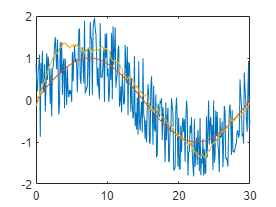


%loop    

plot(t,y_hat);
hold off;

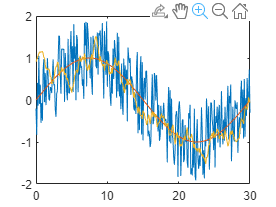


plot(t,noiseey2)
hold on
plot(t,ys)
plot(t,x_hat);
hold off;